TODO:

Ta hänsyn till det vita (i paletten)

Hämta 100 färger från bilden istället (också)

Optimering för att ta bort ett antal färger 100->50 från paletten

Tre kvalitetsmått

"Annan typ av optimering"

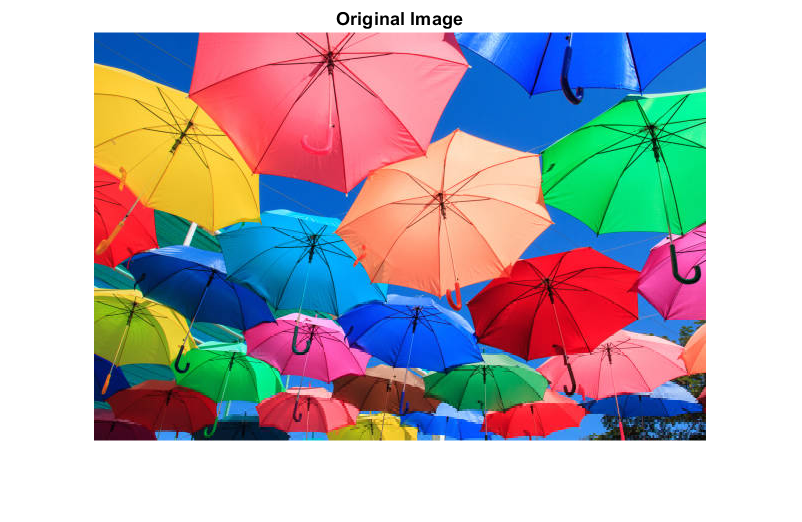

clear
clf

% Settings
partitionSize = 15;
hexFile = 'diverse-natural.hex';
shapeFile = 'circle.png';
imageFile = 'umbrellas.jpg';

im = imread(imageFile);
imshow(im);
title('Original Image');

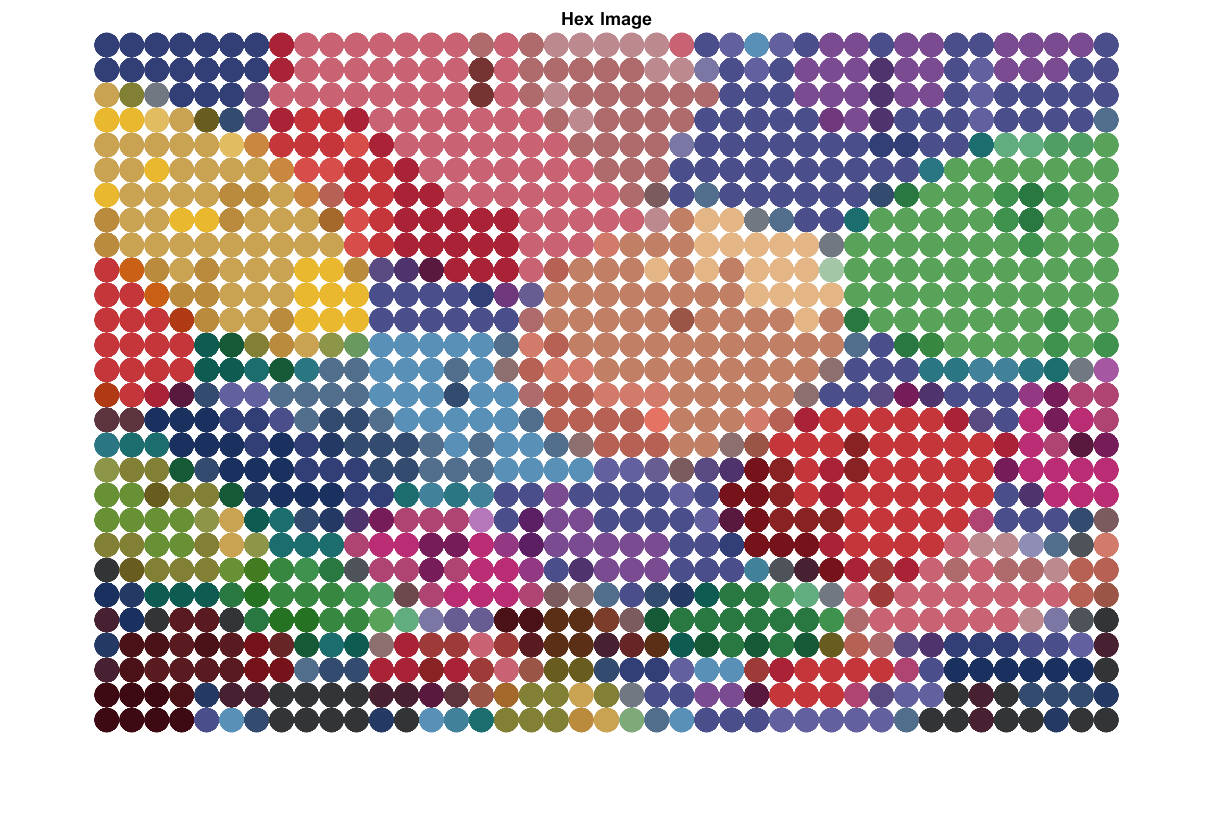


outputHex = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'meanColorDistance');
imshow(outputHex);
title('Hex Image');


% outputReducedColor = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'globalReduction');
% imshow(outputReducedColor);
% title('Reduced Hex Image');

% outputOGColor = reproduceImageWithShapes(partitionSize, shapeFile, imageFile, hexFile, 'imageColorDistance');
% imshow(outputOGColor);
% title('OG Color Image');

% Prepare for quality metrics

% Convert the images to double
load("xyz.mat");
im = im2double(im);
outputHex = im2double(outputHex);

% Determine the target dimensions
targetWidth = 1920;
targetHeight = size(im, 1) * targetWidth / size(im, 2);

% Resize the images using bicubic interpolation while maintaining aspect ratio
im = imresize(im, [targetHeight, targetWidth], 'bicubic');
outputHex = imresize(outputHex, [targetHeight, targetWidth], 'bicubic');
%outputReducedColor = imresize(outputReducedColor, [targetHeight, targetWidth], 'bicubic');
%outputOGColor = imresize(outputOGColor, [targetHeight, targetWidth], 'bicubic');

% SCIELAB
ppi = 141.21; % Lovisa's laptop
d = 500/25.4; % Viewing distance in inches
sampPerDeg = ppi * d * tan(pi/180);
whitepoint = [95.05, 100, 108.9];
format = 'xyz';

fullmetric = scielab(sampPerDeg, rgb2xyz(im), rgb2xyz(outputHex), whitepoint, format);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


mean(mean(fullmetric))

ans = 5.0908


% fullmetric = scielab(sampPerDeg, rgb2xyz(im), rgb2xyz(outputReducedColor), whitepoint, format);
% mean(mean(fullmetric))

% fullmetric = scielab(sampPerDeg, rgb2xyz(im), rgb2xyz(outputOGColor), whitepoint, format);
% mean(mean(fullmetric))

% Delta E

% Convert the images to the CIELAB color space
lab1 = rgb2lab(im);
outputHexLab = rgb2lab(outputHex);
%outputReducedColorLab = rgb2lab(outputReducedColor);
%outputOGColorLab = rgb2lab(outputOGColor);

% Calculate the color difference for each pixel
deltaE = sqrt(sum((lab1 - outputHexLab).^2, 3)); % Euclidean distance in Lab space
mean(deltaE(:))

ans = 42.4000


% deltaE = sqrt(sum((lab1 - outputReducedColorLab).^2, 3)); % Euclidean distance in Lab space
% mean(deltaE(:))

%deltaE = sqrt(sum((lab1 - outputOGColorLab).^2, 3)); % Euclidean distance in Lab space
%mean(deltaE(:))

% SSIM (is it appropriate?????????????????)

ssim(double(outputHex),im)

ans = 0.4684

%ssim(double(outputReducedColor), im)
%ssim(double(outputOGColor), im)